zeta_omega_n = 1

omega_d = 2.2014

s_desired_plus = -1.0000 + 2.2014i

z_c = 0.9230

G_at_pole = -0.0407 + 0.0466i

K = 5.5343

P =
 
  5.534 s + 5.108
 
Continuous-time transfer function.
Model Properties


G =
 
  2 s + 1.846
  -----------
      s^2
 
Continuous-time transfer function.
Model Properties


ZeroPoleForm =
 
  2 (s+0.923)
  -----------
      s^2
 
Continuous-time zero/pole/gain model.
Model Properties


Ideal system: 


ans = struct with fields:
         RiseTime: 0.6154
    TransientTime: 3.4758
     SettlingTime: 3.4758
      SettlingMin: 0.9177
      SettlingMax: 1.2400
        Overshoot: 24.0000
       Undershoot: 0
             Peak: 1.2400
         PeakTime: 1.4276


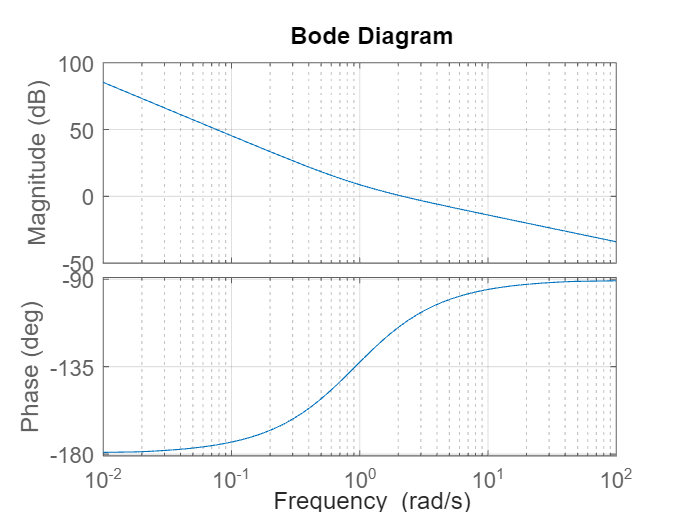

Phase Margin (degrees): 66.9863


Gain Margin (dB): -Inf


CL =
 
     2 s + 1.846
  -----------------
  s^2 + 2 s + 1.846
 
Continuous-time transfer function.
Model Properties


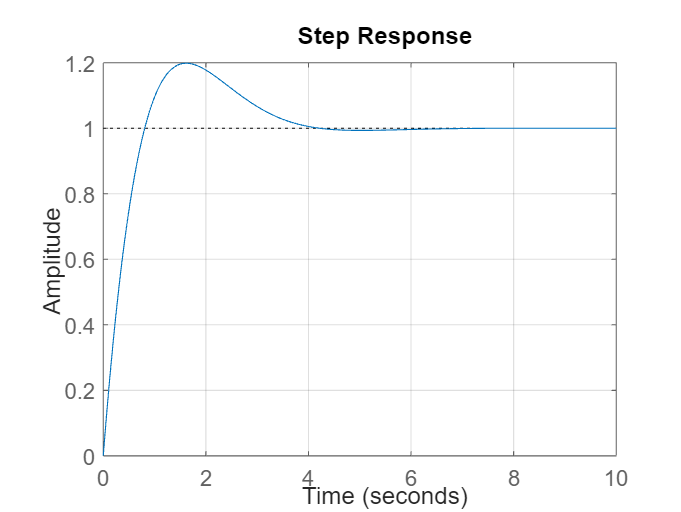

Rise Time: 0.61388 seconds


Overshoot: 19.8488 %


Settling time: 3.637 seconds


Peak time: 1.6118 seconds


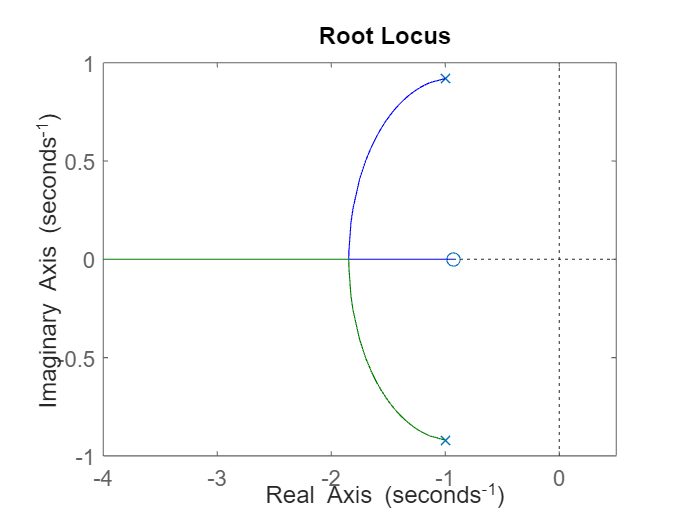

Poles of the system:


poles =   -1.0000 + 0.9198i
  -1.0000 - 0.9198i


Zeros of the system:


zeros_CL = -0.9230

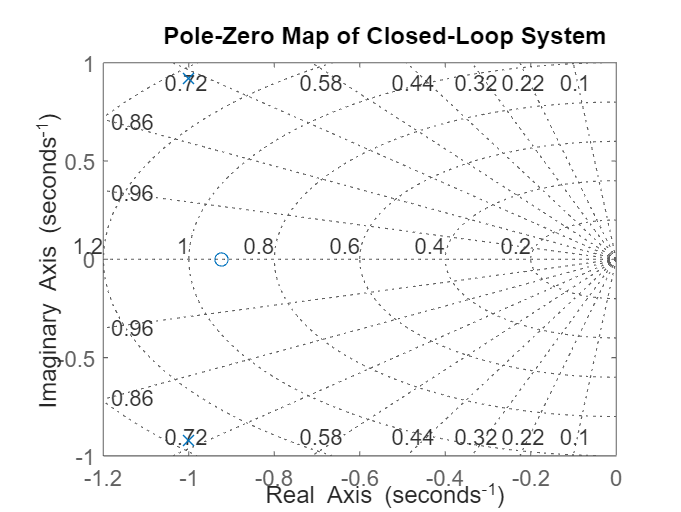

Measured natural frequency:


    1.3587



Damping Ratios (zeta) computed:


    0.7360
    0.7360



% Define transfer function variable

s = tf('s');

%Used the equations in:
%https://ricopic.one/control/control_partial_06-06_06-6_Proportional-derivative_(PD)_controller_design.pdf
% And from youtube video: https://www.youtube.com/watch?v=4lRYUIhLYB8
% And look at this github: https://github.com/tu-darmstadt-ros-pkg/hector_quadrotor/blob/indigo-devel/hector_quadrotor_gazebo_plugins/src/gazebo_quadrotor_simple_controller.cpp

% Original open-loop system
%Needed to create the regulator
%Is the result of the prior system were the controller P(s) was equal 1.
G_orig = tf(0.6653 / (1.841 * s^2));  %Open loop transfer function
%G_orig = tf(0.6653 / (1.841 * s^2 + 0.6653)) %Closed loop transfer function
 
% Design specs
OS_percentage = 24; %Overshoot
T_s = 4; %Settling time in seconds

%Compute damping ratio from overshoot
zeta = -log(OS_percentage / 100) / sqrt(pi^2 + log(OS_percentage / 100)^2);

%Compute natural frequency from settling time
omega_n = 4 / (zeta * T_s);

%Compute desired pole location components
zeta_omega_n = zeta * omega_n   
omega_d = omega_n * sqrt(1 - zeta^2) %Damped natural frequency

%Desired pole locations
s_desired_plus = -zeta_omega_n + 1i * omega_d %Derrived equation
%s_desired_plus = -(4/T_s)*(1-1i*(pi/log(100/OS_percentage))); %Compressed version from PDF
s_desired_minus = -zeta_omega_n - 1i * omega_d;

%Phase of the open-loop G(s) at the desired pole
phi_G = angle(evalfr(G_orig, s_desired_plus));

%Angle from controller zero (phase angle method)
alpha_c = pi - phi_G;

%Zero location of the PD controller
z_c = real(s_desired_plus) + imag(s_desired_plus) / tan(alpha_c)

%Magnitude of G(s) at desired pole
G_at_pole = evalfr(G_orig, s_desired_plus)

%Gain of the PD controller
K = 1 / abs((s_desired_plus - z_c) * G_at_pole)

%Define PD controller
P = K * (s + z_c)
%P = 1;

%PWM to Ang. Vel. Motor transfer function M(s)
%Derrived from O(s)/U(s) = 1/0.1115
M = (1) / (0.1115);

%Thrust function Y(s)
%Derrived from F(s)/O(s) = 1/13.4796
Y = (1) / (13.4796);

%Drone function D(s)
m = 1.7661 + 0.075; %(kg) Drone + raspberry pi
D = tf((1) / (m*s^2));

%Define transfer function for Bode plot
G = tf(P * M * Y * D)
%G = minreal(G);
ZeroPoleForm = zpk(G)

%Ideal system
ideal_sys = tf(omega_n^2, [1, 2*zeta*omega_n, omega_n^2]);
disp('Ideal system: ');
stepinfo(ideal_sys)

% Plot Bode diagram
bode(G)
grid on

% Display the phase- and gain margin
[GM, PM, Wcg, Wcp] = margin(G);
disp(['Phase Margin (degrees): ', num2str(PM)]);
disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

%Plot step respons
CL = feedback(G,1)
t = linspace(0, 10, 1000);
step(CL,t);
grid on;

%Get step response characteristics
S = stepinfo(CL);
%Display rise time
disp(['Rise Time: ', num2str(S.RiseTime), ' seconds'])
%Display overshoot
disp(['Overshoot: ', num2str(S.Overshoot), ' %'])
%Display settling time
disp(['Settling time: ', num2str(S.SettlingTime), ' seconds'])
%Display peak time
disp(['Peak time: ', num2str(S.PeakTime), ' seconds'])

%Find poles:
rlocus(CL);
% Find and display poles
disp('Poles of the system:');
poles = pole(CL)
% Find and display zeros
disp('Zeros of the system:');
zeros_CL = zero(CL)

%Pole-Zero placement (Other method of mapping)
figure;
pzmap(CL);
title('Pole-Zero Map of Closed-Loop System');
grid on;

%Compute actual natural frequency
omega_n_measured = sqrt(real(poles(1))^2 + imag(poles(1))^2);
disp('Measured natural frequency:');
disp(omega_n_measured);

%Compute actual damping ratios for each pole
zeta_values = -real(poles) ./ abs(poles);
disp('Damping Ratios (zeta) computed:');
disp(zeta_values);


%CONTROL SYSTEM DESIGNER
%controlSystemDesigner(G);